# Linear Quarter Car Model

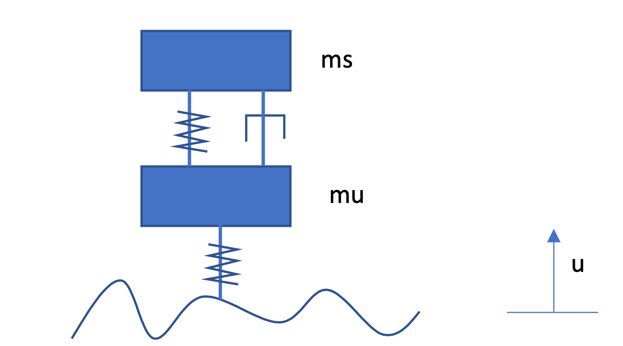

## Generate model

n=2; kappa=200;
[M,C,K,fnl,f_0] = build_model(kappa,n);

## Dynamical system setup 

We consider the stochastic forced system


$$\mathbf{M}\ddot{\mathbf{x}}+\mathbf{C}\dot{\mathbf{x}}+\mathbf{K}\mathbf{x}+\mathbf{f}_{nl}(\mathbf{x},\dot{\mathbf{x}})=\mathbf{f}_{stochastic}(\mathbf{x},t)$$


nRealization=1;
T0=100; %% PSD frequency domain resolution is ~ 1/T0
nPoints=2^14; %% control the accuracy of numerical differential equation
epsilon=1000; %% forcing magnitude
[filterPSD,forcingdof,IC,stochastic_f] = build_stochasticF(n,nPoints,epsilon);
DS = DynamicalSystem();
set(DS,'M',M,'C',C,'K',K,'fnl',fnl,'filterPSD',filterPSD,'stochastic_f',stochastic_f,'linear',false); 
set(DS.Options,'Emax',5,'Nmax',10,'notation','multiindex');
DS.add_random_forcing(nRealization, T0, nPoints,forcingdof);
A=DS.A;B=DS.B;

We assume stochastic forcing of the form that has a specific PSD. We identify the stochastic forcing by input a white noise to a second order system:

                                            
$$\mathbf{M_i}\ddot{\mathbf{x}}+\mathbf{C_i}\dot{\mathbf{x}}+\mathbf{K_i}\mathbf{x}=\mathbf{W}_{white noise}$$


We take the PSD of the response $<\mathbf x_1,\mathbf x_1>$ over the time domain as the input to the Quarter Car system

setting for the SDE solver and allocate desired output PSD pairs

method="filter ImplicitMidPoint";
PSDpair=[1,1; 2, 2; 1, 2];

## Solve full system

[w,outputPSD] = DS.sde_solver(method,IC,PSDpair);

## Calculation of linear response

linear_analytic=DS.compute_linear_PSD(DS.sde.input.omega,DS.sde.input.PSD);

## This section plots the result of the full system response and linear analytical

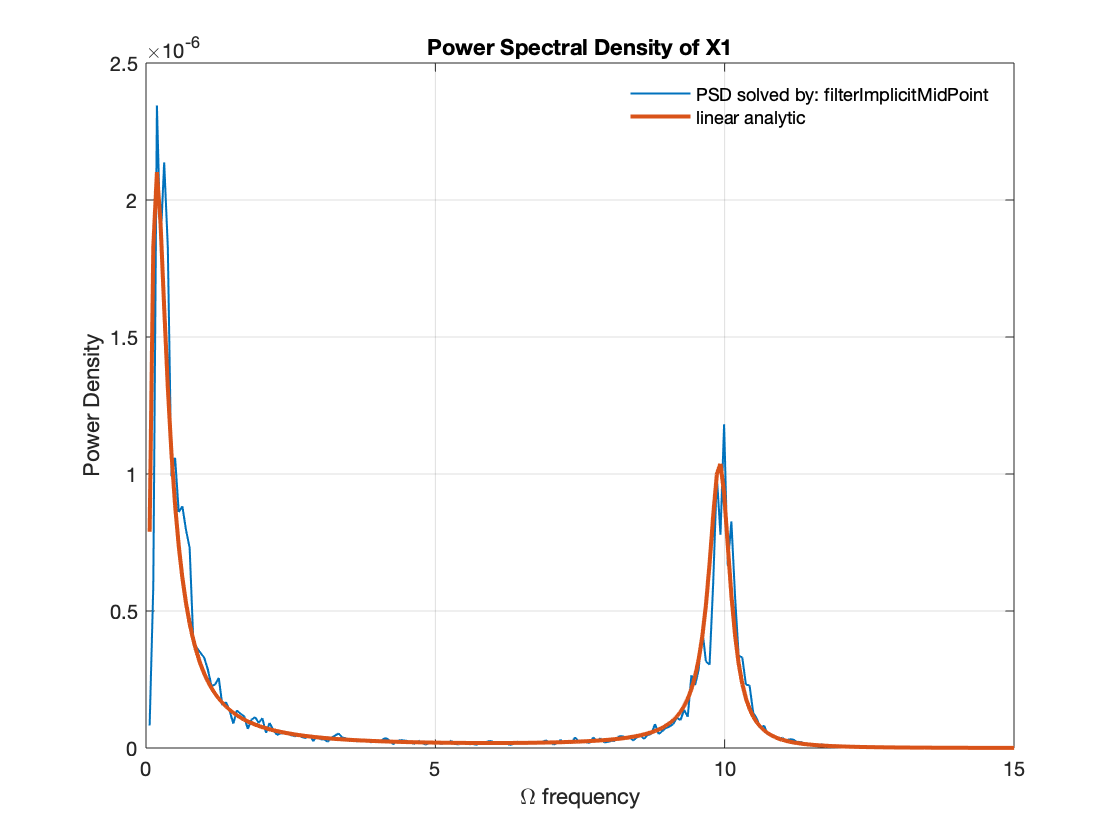

figure
plot(w,outputPSD(1,:),'linewidth',1)
hold on
plot(w,linear_analytic(1,:),'linewidth',2)
xlim([0,15])
xlabel('\Omega frequency')
ylabel('Power Density')
legend(strcat('PSD solved by ', ": ",method), 'linear analytic')
legend('boxoff')
title('Power Spectral Density of X1')
grid on

## SSM setting and compute PSD from SSM

S = SSM(DS);
set(S.Options, 'reltol', 0.1,'notation','multiindex')
masterModes = [1,2];
S.choose_E(masterModes);
order = 5; % SSM approximation order
[W0, R0] = S.compute_whisker(order);
ssmPSD=S.extract_PSD([0 20], order,"filter");

## Compare the results of SSM, full system response and linear response

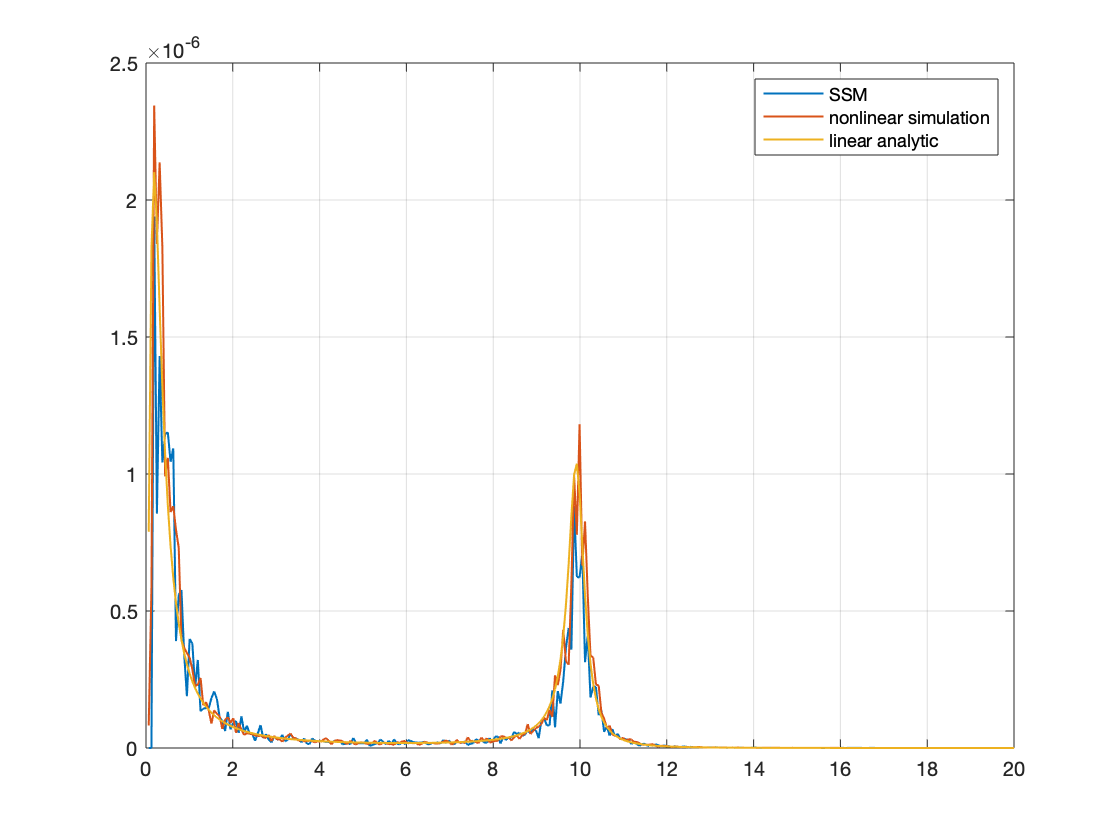

figure
plot(ssmPSD.omega,ssmPSD.PSD,'linewidth',1)
hold on
plot(w,outputPSD(1,:),'linewidth',1)
hold on
plot(w,linear_analytic(1,:),'linewidth',1)
legend('SSM','nonlinear simulation','linear analytic')
xlim([0,20]);
grid on